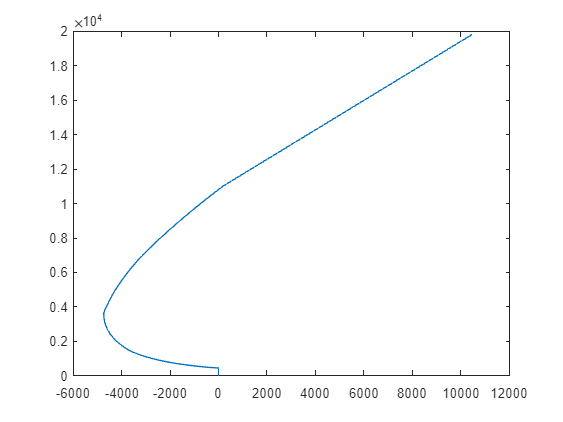

%24/02/2024 A NON-WORKING INTIAL VERSION OF A B SPLINE ALGORITHM
%KNOT VECTOR IS WRONG, NO OPEN UNIFORM USAGE
P1 = [0,100];
P2 = [20,20];
P3 = [75,40];
P4 = [50,40];
P5 = [100,10];
%for k = 2
t1 = 10;
t2 = 20;
t3 = 30;
t4 = 40;
t5 = 50;
t6 = 60;
t7 = 70;
Knot = [t1,t2,t3,t4,t5,t6,t7];
SumN = 0;
SumNx = 0;
SumNy = 0;
NStack = [];
NStackx = [];
NStacky = [];
T = [];
for t = 0:1:80
    if (t1<=t)
        if (t<t2)
            N1k1 = 1;
        end
    else
        N1k1 = 0;
    end
    if (t2<=t)
        if (t<t3)
            N2k1 = 1;
        end
    else
        N2k1 = 0;
    end
    if (t3<=t)
        if (t<t4)
            N3k1 = 1;
        end
    else
        N3k1 = 0;
    end
    if (t4<=t)
        if (t<t5)
            N4k1 = 1;
        end
    else
        N4k1 = 0;
    end
    if (t5<=t)
        if (t<t6)
            N5k1 = 1;
        end
    else
        N5k1 = 0;
    end
    if (t6<=t)
        if (t<t7)
            N6k1 = 1;
        end
    else
        N6k1 = 0;
    end
    N1k2 = ((t-t1)/(t2-t1))*N1k1 + ((t3-t)/(t3-t2))*N2k1;
    N2k2 = ((t-t2)/(t3-t2))*N2k1 + ((t4-t)/(t4-t3))*N3k1;
    N3k2 = ((t-t3)/(t4-t3))*N2k1 + ((t5-t)/(t5-t4))*N4k1;
    N4k2 = ((t-t4)/(t5-t4))*N2k1 + ((t6-t)/(t6-t5))*N5k1;
    N5k2 = ((t-t5)/(t6-t5))*N2k1 + ((t7-t)/(t7-t6))*N6k1;
    SumNx = SumNx + N1k2*P1(1,1) + N2k2*P2(1,1) + N3k2*P3(1,1) + N4k2*P4(1,1) + N5k2*P5(1,1);
    SumNy = SumNy + N1k2*P1(1,2) + N2k2*P2(1,2) + N3k2*P3(1,2) + N4k2*P4(1,2) + N5k2*P5(1,2);
    %SumN = SumN + N1k2*P1 + N2k2*P2 + N3k2*P3 + N4k2*P4 + N5k2*P5;
    NStackx = [NStackx, SumNx];
    NStacky = [NStacky, SumNy];
    %NStack = [NStack , SumN];
    %T = [T , t];
end
plot(NStackx, NStacky)

Knot

Knot =     10    20    30    40    50    60    70


ControlPoints = [P1; P2; P3; P4; P5]

ControlPoints =      0   100
    20    20
    75    40
    50    40
   100    10


%plot(NStack)

